# District Heating Pipe 

You can find a brief description of the modelling approaches in [tbd].

[Open Live Script in Matlab](matlab:open('DistrictHeatingPipeDemo.mlx')) 

clear; close all, clc;

In the following sections the different submodels will be build. Some of them in an seperate scripts. You can find the scripts in the demo-directory.

## System description

In the following figure, an overview of the district heating pipe framework is shown

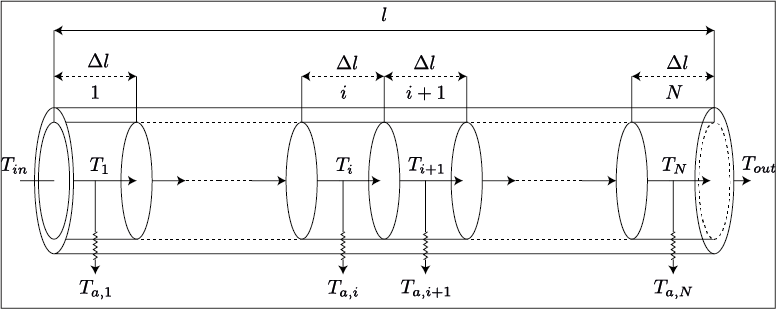

**Figure 1: Principial structure of a disaggregated district heating pipe with a defined amount of segment N**

In this framework, the pipe is discretized along the direction of the flow into N (N>1) equal segments. The amount of segment N influences the precision of the calculation.

This model relies upon/uses the following assumptions:

- Constant fluid parameters (density $\rho
$, heat capacity $c_{p}$, viscosity $\mu$)

- Constant temperature within the volume segment 

- No change in diameter along the lenngth of pipe $l$

## Physics of District Heating Pipes

For the flow of fluid within a pipe, the conservation laws has to hold

- Conservation of mass

- Conservation of energy

- Conservation of momentum

The implementation of the conservation laws are presented in the following:

### Conservation of mass

In this framework, static mass balance is implemented without the consideration of mass storage effects or density changes. Furthermore, the fluid is assumed to be imcopressible. 


$$\dot{m}_{in} +\dot{m}_{out} = 0$$


### Conservation of energy

As shown in Figure 1, this framework makes use the the discretization of the pipe along the flow direction into N equal segments. The distributed temperature of the pipe segments are denoted by $T_{1}, \dots , T_{N}$  with the corresponding ambient temperature given by $T_{a,1}, \dots , T_{a,N}$, and the inflow temperature denoted by $T_{in}$, with $T_{out}$ denoting the outflow temperature. 

Using a set of differential equations, the dynamic behavior of the a discretized pipe can be generally described


$$
            C_{th,p,1}\frac{dT_{1}}{dt} = -(\dot{m}c_{p} + G_{th,p,1})T_{1} + \dot{m}c_{p}T_{in} + G_{th,p,1}T_{a,1} \\ 
            C_{th,p,2}\frac{dT_{2}}{dt} = -(\dot{m}c_{p} + G_{th,p,2})T_{2} + \dot{m}c_{p}T_{1} + G_{th,p,2}T_{a,2} \\ 
            \vdots   \\
            C_{th,p,N}\frac{dT_{N}}{dt} = -(\dot{m}c_{p} + G_{th,p,N})T_{N} + \dot{m}c_{p}T_{N-1} + G_{th,p,N}T_{a,N}$$


with $C_{th,p,i}$  and $G_{th,p,i}$ representing the thermal capacitance and  the thermal codunctace in the corresponding segment $i$. 

Generally $C_{th,p,i}$  can be described as how much heat must be added to raise the temperature of that part of the system by one degree.$C_{th,p,i}$ depends on the density $\rho$, cross section area $A$, segment length $\Delta{l}$, and heat capacity $c_{p}$


$$C_{th,p,i} = \rho \cdot A_{i} \cdot  \Delta{l} \cdot c_{p} $$


Thermal conductance $G_{th,p,i}$ quantifies the heat flow through a body per unit temperature difference. The heat transfer towards the ambient covers a number of different processes, which occurs on the different layers of the pipe (pipe wall, insulation layer, and so on). Generally in district heating pipes, this type of heat loss is quantified using a (linear) heat loss factor $U$

### Conservation of momentum

The momentum balance for pipe flow is based on the law of conservation of momentum, which states that the net force acting on a control volume of fluid is equal to the rate of change of momentum within that volume. In simplified terms, for pipe flow, it analyzeshow forces (such as pressure, gravity, and friction) affect the movement of fluid through the pipe.

Using the euler equation as a basis, the momentum balance for a one dimensional pipe flow can be described as such


$$\frac{d\dot{m}}{dt}\cdot L + \Delta q = \Delta p - \Delta p_{ext} $$


where $\Delta{q}$ expresses the difference in dynamic pressure, $L$ represents the inertance, $\Delta p_{ext}$ represent external pressure loss (gravity, friction, etc.), $\dot{m}$ represents the mass flow of the fluid, and $\Delta{p}$ represents the pressure difference between the input and output. Within this framework, the term $L$ is neglected and $\Delta{p}_{ext}$ is limited to the pressure loss due to friction. 

In cylindrical pipes, the pressure loss due to friction can be quantified using Darcy-Weisbach equation. 


$$\frac{\Delta p}{l} = \lambda\cdot \frac{8\cdot {\dot{m}}^2}{\pi^{2}\cdot \rho \cdot d^{5}}$$


where $l$ is the length of the pipe segment, $\lambda$ is the pipe friction factor, $d$ is the hydraulic diameter of the pipe, and $\rho$ is the density of the fluid. The friction factor $\lambda$ is also widely known as Darcy-Weisbach friction factor and depends on the characteristic of the pipe and the characteristics of the fluid flow. Depending on the flow regimes: laminar, transitional, turbulent, the calculation of $\lambda$ differs. Within this framework, only laminar ($Re \le 2300$) and turbulent ($Re \gt 2300$) flow regimes are considered. 

For laminar flow regime:


$$\lambda = \frac{64}{Re}$$


For Turbulent flow regime:


$$\frac{1}{\sqrt{\lambda}} = -2 \log_{10} \left( \frac{2.51}{Re \sqrt{\lambda}} + \frac{\varepsilon}{3.71 d} \right)$$


## Application of the MTI Framework for District heating Pipes

In the following the application of the MTI framework for each of the conservation laws are presented

### Conservation of mass

As mentioned above, the conservation of mass are without density changes and storage effects


$$\dot{m}_{in} +\dot{m}_{out} = 0$$


In this case $\dot{m}_{in}$ is set as input $u_1$ and $\dot{m}_{out}$ as output $y$

% eq = {"u1+y1=0";};
% 
% massEquation = sym2dmss(eq, 0);
% massEquation.inputName = "p_1_m_inlet";
% massEquation.algebraicName = "p_1_m_outlet";

eq = {"u1+u2=0";};
massEquation = sym2dmss(eq, 0);
massEquation.inputName = ["p_1_m_inlet","p_1_m_outlet"];

### Conservation of energy

For the conservation of energy, differential equations are first converted to the corresponding input, outputs and state variables. 

- 
$$x_i \rightarrow T_{i}$$


- 
$$\dot{x}_i \rightarrow \frac{dT_{i}}{dt}$$


- 
$$u_1 \rightarrow \dot{m}_{in}$$


- 
$$u_{2} \rightarrow T_{in}$$


The following values are assumed to be constant

- 
$$T_a$$


- 
$$G_{th,p}$$


- 
$$C_{th,p}$$


Using the above mentioned assumptions, the differential equationscan be represented using


$$
            C_{th,p}\cdot \dot{x}_1 = -u_1\cdot x_1\cdot c_{p} - x_1 \cdot G_{th,p} + u_1\cdot u_2\cdot c_{p} + G_{th,p}\cdot T_{a} \\ 
            C_{th,p}\cdot \dot{x}_2 = -u_1\cdot x_2\cdot c_{p} - x_2 \cdot G_{th,p} + u_1\cdot x_1\cdot c_{p} + G_{th,p}\cdot T_{a} \\ 
            \vdots   \\
            C_{th,p}\cdot \dot{x}_N = -u_1\cdot x_N\cdot c_{p} - x_N \cdot G_{th,p} + u_1\cdot x_{N-1}\cdot c_{p} + G_{th,p}\cdot T_{a} \\ $$


This can be implemented either using symbolic equations or using the corresponding matrices. 

Basic assumptions

N = 2; % 2 segments
l = 10; % pipe length in m 
cp = 4190; % specific heat capacity in J/kgK
rho = 1000; % fluid density in kg/m3
di = 263*1e-3; % inner pipe diameter in m
U = 0.1295; % linear heat transfer coeffieicnt in W/m*K 
delta_x = l/N; % pipe segment length in m
A_pipe = pi()*di*di/4; % internal cross section area of pipe in m2
C_th = A_pipe*rho*cp*delta_x; % thermal capacitance of fluid in J/K
G_th = U * delta_x; % thermal conductance in W/K
Ta = 273.15 + 9; % ambient temperature of 9°C

#### Variant 1: Symbolic equations

This variant makes use of symbolic equation. This is much more convenient as the parameters are generated automatically. But The parsing of the symbolic equations are significantly slower. 

For bigger systems, using parameters directly is preferred.

% Generate equations sequent
eq = {"Cth*xp1 = -u1*x1*cp - Gth*x1 + u1*u2*cp+ Gth*Ta"};
for i = 2:1:N
    eq{i} = sprintf("Cth*xp%i = -u1*x%i*cp - Gth*x%i + u1*x%i*cp+ Gth*Ta", i, i, i, i-1);
end

% Generate model tensor
energyEquations = sym2dmss(eq, 0, ["xp", "x", "u", "y"]);

Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


symbolicParameters = [sym("cp") sym("Cth") sym("Gth") sym("Ta")];
numericParameters = [cp C_th G_th Ta];
energyEquations = energyEquations.replaceSymbolicParameters(symbolicParameters, numericParameters);
energyEquations.symbolicEquations

$$ans = \left(\begin{array}{c} \frac{259\,x_{1}}{400}+\frac{2444079178552069\,{\mathrm{xp}}_{1}}{2147483648}-4190\,u_{1}\,u_{2}+4190\,u_{1}\,x_{1}-\frac{6427907703699407}{35184372088832}=0\\ \frac{259\,x_{2}}{400}+\frac{2444079178552069\,{\mathrm{xp}}_{2}}{2147483648}-4190\,u_{1}\,x_{1}+4190\,u_{1}\,x_{2}-\frac{6427907703699407}{35184372088832}=0 \end{array}\right)$$

#### Variant 2: Use parameter matrices directly

Based on the differential equations, the following structure matrix can be derived 


$$\begin{array}{c|ccc|ccc|c|ccc|c}
 Dimensions & \leftarrow & N & \rightarrow & \leftarrow & N & \rightarrow & 1 & \leftarrow & N & \rightarrow & 1\\
\hline
\dot{x}_{1} & 1 &  &  &  &  &  &  &  &  & & 0 \\
\vdots      &   & \ddots &   &  &  &  &  &  &  & &  \\
\dot{x}_{N} &   &   & 1 &  &  &  &  &  &  &  &\\[1ex]
x_{1}       &   &   &   & 1 &  &  &  & 1 &  &  & \vdots \\
\vdots      &   &   &   &   & \ddots &   &   &   &   \ddots &  &\\
x_{N}       &   &   &   &   &   & 1 &   &   &   & 1  &\\[1ex]
u_{1}       &   &   &   &   &   &   & 1 & 1 & \cdots & 1 & \\
u_{2}       &   &   &   &   &   &   & 1 &   &  &  & 0 \\
\end{array}$$


jA = [1:N*2+1, ... This part is the "diagonal" matrix for xd1 up to u1
    N*2+1, ... This part is for the u2 
    N*2+2:N*3+1,... This part is for the "second" diagonal of x1 to xN
    N*2+2:N*3+1 ... This part is for the horizontal of u1
    ];
iA = [1:N*2+1, ... This part is the "diagonal" matrix for xd1 up to u1
    N*2+2, ... This part is for the u2 
    N+1:N*2 ...This part is for the "second" diagonal of x1 to xN
    (N*2+1)*ones(1,N) ... This part is for the horizontal of u1
    ];
smat = sparse(iA,jA,1,N*2+2,N*3+2);

full(smat)

ans =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     1     0     0
     0     0     0     1     0     0     1     0
     0     0     0     0     1     1     1     0
     0     0     0     0     1     0     0     0


For the representation using tensor, $\Phi$ matrix has to also be generated. The amount of rows of the $\Phi$ matrix depends on the amount of segment $N$ of the pipe


$$\begin{array}{c|ccc|ccc|cccc|c|c|}
1 & C_{th} &  & &G_{th,p} &  &  & -cp &  cp & & &  -T_{amb}\cdot G_{th,p}\\
\vdots &  &\ddots & &  & \ddots& &  &\ddots & \ddots &&  \vdots\\
N& &  & C_{th} &  &  & G_{th,p}& & & -cp & cp& -T_{amb}\cdot G_{th,p}\\
\end{array}$$


multiplicator = ones(1,N);
jPhi_cth = 1:N;
vPhi_cth = [C_th*multiplicator ];

% dx*k are also a diagonal
%iPhi_dxk = [1:obj.N];
jPhi_dxk = [N+1:N*2];
vPhi_dxk = [G_th*multiplicator ];

jPhi_neg_cp = [N*2+1:N*3];
vPhi_neg_cp = [-cp*multiplicator ];

jPhi_cp = [N*2+2:N*3+1];
vPhi_cp = cp*multiplicator ;

jPhi_const = [(N*3+2)*multiplicator ];
vPhi_const = [(-Ta*G_th)*multiplicator ];

iPhi = [repmat(1:N,1,5)];
jPhi = [ jPhi_cth, jPhi_dxk,jPhi_neg_cp, jPhi_cp,jPhi_const];
vPhi = [vPhi_cth, vPhi_dxk,vPhi_neg_cp, vPhi_cp,vPhi_const];

H1 = hyCPN1();
% Put the "correct" parts of the tensor 
H1.F.input = smat(N*2+1:N*2+2,:);
H1.F.stateDerivative = smat(1:N,:);
H1.F.state = smat(N+1:N*2,:);
% Put the sparse matrix here directly 
%H1.phi.equality = phiMat; 
H1.phi.equality = sparse(iPhi,jPhi,vPhi, N, N*3+2);

full(sparse(iPhi,jPhi,vPhi, N, N*3+2))

ans = 1.0e+06 *

    1.1381         0    0.0000         0   -0.0042    0.0042         0   -0.0002
         0    1.1381         0    0.0000         0   -0.0042    0.0042   -0.0002


energyEquations = dmss(H1,0);
energyEquations.stateName = "p_1_t_" + string(1:N);
energyEquations.inputName = ["p_1_m_inlet","p_1_t_inlet"];
%energyEquations.algebraicName = "p_1_t_outlet";
energyEquations.symbolicEquations

$$ans = \left(\begin{array}{c} \frac{259\,x_{1}}{400}+\frac{2444079178552069\,{\mathrm{xp}}_{1}}{2147483648}-4190\,u_{1}\,u_{2}+4190\,u_{1}\,x_{1}-\frac{3213953851849703}{17592186044416}=0\\ \frac{259\,x_{2}}{400}+\frac{2444079178552069\,{\mathrm{xp}}_{2}}{2147483648}-4190\,u_{1}\,x_{1}+4190\,u_{1}\,x_{2}-\frac{3213953851849703}{17592186044416}=0 \end{array}\right)$$

To connect the temperature from the last segment to the outlet temperature, a submodel is created to both equations


$$T_{N} - T_{out} = 0$$


H1 = hyCPN1();
H1.F.input = eye(2);
H1.phi.equality = [1, -1];
tempConnector = dmss(H1,0);
tempConnector.inputName = ["p_1_t_"+N , "p_1_t_outlet"];

Both models can now be connected together

energyModel = connect(tempConnector, energyEquations);

Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.


### Conservation of momentum

Considering the nonlinearity of the Darcy friction factor Figure 2, the calculation of the head loss due to friction within the pipe has to be done in a number of steps.

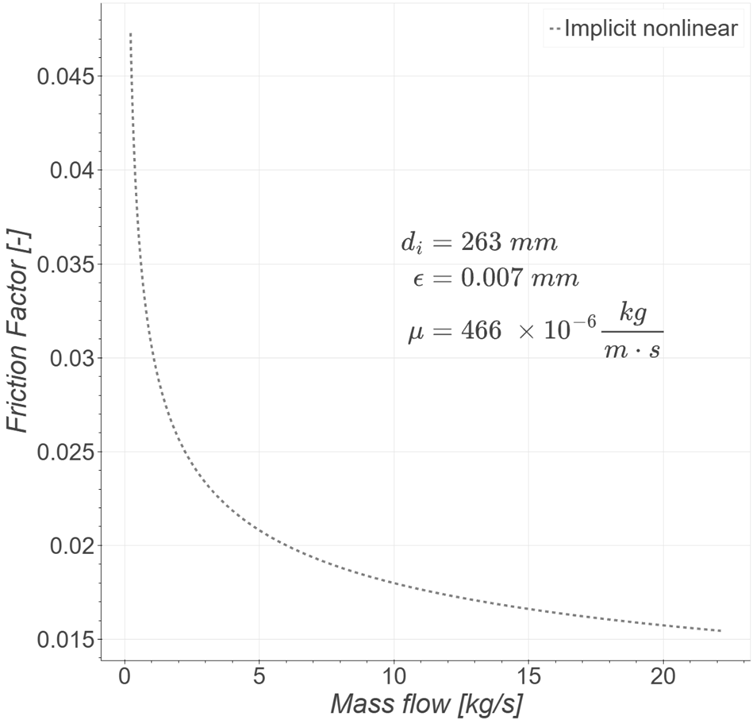

**Figure 2: Examplary friction factor for different mass flows on a single diameter**

#### Determination of the flow direction

As the direction of the flow is important for the pressure loss within the pipe, a submodel is required to determine the direction of the flow.

For this purpose, the following inputs are defined

- 
$$u_1 \rightarrow \dot{m}_{in}$$


-  boolean variable ($z_1$)

The following equation is generated out of it


$$2 \cdot u_1 \cdot z_1 - u_1 \leq 0$$


H1 = hyCPN1();
H1.F.input = [1,1];
H1.F.boolean = [1,0];
H1.phi.inequality = [2, -1];
fluidAbsM = dmss(H1,0);
fluidAbsM.inputName = "p_1_m_inlet";
fluidAbsM.booleanName = "mass_flow_bool";

#### Absolute value of the mass flow

Generally in a fluid flow within a pipeline, the direction of the flow can change. 

The value of the friction factor is, however, always positive regardless of the direction of the flow. 

In simplified terms, the approximation of the friction factor for both positive or negative direction can be use using only the absolute value of the mass flow. 

For this purpose, the following inputs are defined

- 
$$u_1 \rightarrow \dot{m}_{in}$$


- 
$$u_2 \rightarrow \dot{m}_{abs}$$


- 
$$u_3 \rightarrow \dot{m}_{abs}$$


- $u_4 \rightarrow $ boolean variable ($z_1$)

$u_2$ and $u_3$ are duplicates, as both variables are needed for later steps. This therefore goes into the following set of equations.


$$2\cdot u_1 \cdot u_4 - u_1 + u_2 = 0  \\
u_2 - u_3 = 0$$


H1 = hyCPN1();
H1.F.input = [[sparse([2,1,1,4,3],[1,2,3,3,4],1,4,4)]];

H1.phi.equality = [[1, -1, 2, 0; -1, 0, 0, 1]];
massFlowAbs = dmss(H1, 0);
massFlowAbs.inputName = ["p_1_m_inlet","mass_flow_abs","mass_flow_square","mass_flow_bool"];
massFlowAbs.symbolicEquations

$$ans = \left(\begin{array}{c} u_{2}-u_{1}+2\,u_{1}\,u_{4}=0\\ u_{3}-u_{2}=0 \end{array}\right)$$

#### Differentiation of Laminar and Turbunlent flow

The conservation of momentum starts with the consideration, whether the corresponding flow is laminar or turbulent. 

For this boolean variable is required. For this case, Reynolds Number of 2300 is used as a limit. 

The "absolute" value of the mass flow is used here to simplify the consideration of the turbulent and laminar flow

ReLimit = 2300;
di = 21.7*1e-3;
mu = 466*1e-6;
rho = 1000;

% Calculation of the mass flow required to get Re = 2300
mpmin = ReLimit*(pi*di*mu)/4;


For this calculation, two inputs are required:

- 
$$\dot{m} \rightarrow u_1$$


- boolean variable ($z_1$) $\rightarrow u_2$

The resulting equation is then as such 


$$(2\cdot {u_{2}} -1)\cdot (u_{1} - \dot{m}_{min}) \leq 0 \\
\downarrow \\
2\cdot u_1 \cdot u_2 - 2\cdot u_2 \cdot \dot{m}_{min} - u_1 + \dot{m}_{min} \leq 0$$


H1 = hyCPN1();
% The input is in the following repesentation (matrix)
%       c
%   u1  0	1	0	1
%   u2  0	0	1	1
H1.F.input = [sparse([1,2,1,2],[2,3,4,4],1,2,4)];
% Directly add it to the inequality
H1.phi.inequality = [mpmin, -1, -2*mpmin, 2];
booleanLamTurb = dmss(H1,0);
booleanLamTurb.inputName = ["mass_flow_abs","Re_bool"];

#### Friction factor for laminar flow

For laminar flow regime, the friction factor can be calculated as such:


$$\lambda = \frac{64}{Re}$$


where $Re$ can be expressed in terms of $\dot{m}$


$$Re = \frac{4 \cdot \dot{m}}{\pi\cdot{d}\cdot \mu}$$


By reformulating the equation and substituting $Re$, the following equation can be derived


$$\lambda \cdot  \frac{4 \cdot \dot{m}}{\pi\cdot{d}\cdot \mu} - 64 = 0$$


Due to the nature of the equation, the equation cannot be solved for $\dot{m} = 0 $. 

To ensure the equation is always solvable, adding a small number $\epsilon$ to the $\dot{m}$ ensures the equation is always solvable by slightly reducing the accuracy of the equation. 


$$\lambda \cdot  \frac{4 \cdot (\dot{m} + \epsilon)}{\pi\cdot{d}\cdot \mu} - 64 = 0$$


By setting

- 
$$\dot{m} \rightarrow u_1$$


- 
$$\lambda \rightarrow u_2$$


- 
$$ \frac{4}{\pi\cdot{d}\cdot \mu} \rightarrow ReF \; (const.)$$


The equation can be transformed into


$$ReF \cdot u_1 \cdot u_2  + ReF \cdot \epsilon \cdot u_2 - 64 =0$$


ReF= 4/(pi*di*mu);
m_eps = 1e-6;
H1 = hyCPN1();
H1.F.input = [[sparse([2,2,1],[1,2,2],1,2,3)]];
H1.phi.equality = [ReF*m_eps, ReF ,-64];
darcyLaminar = dmss(H1,0);
darcyLaminar.inputName = ["mass_flow_abs","lam_friction_factor"];

#### Friction factor for turbulent flow

For turbulent flow regime, the friction factor can be calculated as such:


$$\frac{1}{\sqrt{\lambda}} = -2 \log_{10} \left( \frac{2.51}{Re \sqrt{\lambda}} + \frac{\varepsilon}{3.71 d} \right)$$


This factor has to however be solved implicitly (iteratively).

Such equations can however be approximated using implicit multilinear approximation. 


$$0 = \Phi_{11}\cdot(1 - |F_{11}| +  |F_{11}| \cdot \dot{m}_{abs}) \cdot(1 - |F_{21}| +  |F_{21}| \cdot \dot{m}_{abs})\cdot(1 - |F_{31}| +  |F_{31}| \cdot \lambda_{turb}) + \\
\Phi_{12}\cdot(1 - |F_{22}| +  |F_{22}| \cdot \dot{m}_{abs}) \cdot(1 - |F_{32}| +  |F_{32}| \cdot \dot{m}_{abs})$$


In the context of this work, the method of least squares is used to calculate the required parameters $F$ and $\Phi$ depending on the $\epsilon$ and $d$

For this calculation three inputs are defined:

- 
$$\dot{m}_{abs} \rightarrow u_1$$


- 
$$\dot{m}_{abs} \rightarrow u_2$$


- 
$$\lambda_{turb} \rightarrow u_3$$


eps_pipe = 7e-06; % pipe roughness in m
di = 0.0217; % pipe inner diameter in m
% Load structure and phi matrices from a mat file
pipeFrictionFactor = load('pipeFrictionFactorMTINeu.mat', 'pipeFrictionFactor');
pipeFrictionFactor = pipeFrictionFactor.('pipeFrictionFactor');
% The variable is structured as a nested table with pipe roughness as
% column name
pipeFrictionFactor

pipeFrictionFactor = table
       7e-06    
    ____________

    {1×28 table}


% inside the nested table, the inner diameter of the pipe is used as
% column name
pipeFrictionFactor.(string(eps_pipe)){1}

ans = 1×28 table
      0.0217        0.0273        0.036         0.0419        0.0539        0.0697        0.0825        0.1071        0.1325        0.1603        0.1847        0.2101        0.2345        0.263         0.3127        0.3444        0.3938        0.4444        0.4954        0.5462        0.5958        0.6458        0.695         0.746         0.7954        0.8464        0.894         0.994   
    __________    __________    __________    _________

% in the inner table a struct cointaining s matrix and phi matrix. These
% values are to be used for the construction of the multilinear equation
pipeFrictionFactor.(string(eps_pipe)){1}.(string(di))

ans = struct with fields:
      s: [3×2 double]
    phi: [-0.4889 -0.0084]



s = pipeFrictionFactor.(string(eps_pipe)){1}.(string(di)).s;
phi = pipeFrictionFactor.(string(eps_pipe)){1}.(string(di)).phi;

% Now generate the hyCPN1
H = hyCPN1();
% To simplify put everything as an input.
% It is not so problematic as it will be connected to other
% models on the next steps
H.F.input = [s(1:3,:)];
%H.F.algebraic = [s(2:end,:)];
H.phi.equality = [phi];
darcyFactor = dmss(H,0);
darcyFactor.inputName = ["mass_flow_abs","mass_flow_square","turb_friction_factor"];

#### Combined friction factor

Due to the equations required for Darcy friction factor for both turbulent and laminar flow regimes, an equation is used to calculate the "sum" of the friction factors depending on the mass flow. 

For this purpose, the following variables are defined:

- 
$$\lambda_{lam} \rightarrow y_1$$


- 
$$\lambda_{turb} \rightarrow y_2$$


- 
$$\lambda \rightarrow y_3$$


- boolean variable ($z1
$) 

The resulting equation is configured as such


$$z_1 \cdot y_1  - z_1 \cdot y_2  +  y_2  - y_3 = 0$$


H1 = hyCPN1();
H1.F.algebraic = [[sparse([2,3,1,2],[1,2,3,4],1,3,4)]];
%H1.F.input = [[sparse(1,4,1,1,4)]];
H1.F.boolean = [[sparse([1,1],[3,4],1,1,4)]];
H1.phi.equality = [1,-1,1,-1];
frictionFactor = dmss(H1,0);
frictionFactor.algebraicName = ["lam_friction_factor","turb_friction_factor","friction_factor"];
frictionFactor.booleanName = ["Re_bool"];


#### Calculation of pressure los due to friction

For one directional flow, the following equation can be used to calculate the pressure loss due to friction


$$p_{out} - p_{in} + \frac{8}{\pi^{2}\cdot \rho \cdot d^{5}} \cdot \dot{m}_{abs} \cdot \dot{m}_{abs} \cdot \lambda = 0
$$


However, due to the flow being biderctional, the equation has to be modified to ensure the direction of the flow is considered. For this purpose, a boolean variable is implemented.

The equation is therefore adjusted to the following equation using $FD$ as a boolean variable (1 for positive and 0 for negative)


$$p_{out} - p_{in} + \frac{8}{\pi^{2}\cdot \rho \cdot d^{5}} \cdot \dot{m}_{abs} \cdot \dot{m}_{abs} \cdot \lambda \cdot (2\cdot FD-1)= 0
$$


By defining the variables as such

- 
$$p_{in} \rightarrow u_1$$


- 
$$\lambda \rightarrow u_2$$


- 
$$FD \rightarrow u_3$$


- 
$$\dot{m}_{abs} \rightarrow y_1$$


- 
$$p_{out} \rightarrow y_2$$


- 
$$\dot{m}_{abs} \rightarrow y_3$$


- 
$$ \frac{8}{\pi^{2}\cdot \rho \cdot d^{5}}  \rightarrow PF \; (const.)$$


The equation can be implemented in the MTI framework using


$$y_2 - u_1 + 2 \cdot PF \cdot u_2 \cdot u_3 \cdot y_1 \cdot y_3 - PF \cdot u_2 \cdot y_1 \cdot y_3  = 0
$$


factor = 8*l/(rho*pi()*pi()*power(di,5));
H1 = hyCPN1();
H1.F.input = [[sparse([1,2,2,3,4],[2,3,4,4,1],1,4,4)]];
H1.F.algebraic = [[sparse([1,2,1,2],[3,3,4,4],1,2,4)]];
%H1.F.boolean = [[sparse([1],[4],1,1,4)]];
H1.phi.equality = [[1, -1, factor, -2*factor]];
pressureLoss = dmss(H1, 0);
pressureLoss.algebraicName = ["mass_flow_square","mass_flow_abs"];
%pressureLoss.booleanName = ["mass_flow_bool"];
pressureLoss.inputName = ["p_1_p_inlet","friction_factor","mass_flow_bool","p_1_p_outlet"];

#### Overall pressure model

For the overall pressure model, each of the submodels has to be connected to one another

pressureModel = connect(fluidAbsM,...
                booleanLamTurb,...
                darcyLaminar,...
                darcyFactor,...
                frictionFactor, ...
                massFlowAbs, ...
                pressureLoss);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 4 column(s) and 0 equation(s) with trivial Reduction due to duplications.


### Overall Model

In the following figure, a simplified schematic view of the overal pipe model is shown

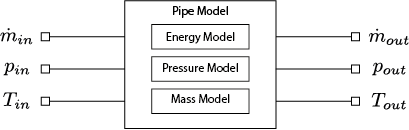

**Figure 2: Simplified schematic view of the overal pipe model**

As shown in the figure, the model comes with 6 connection points. 

The overal model is generated by connecting the different submodels with eachother

pipeModel = connect(energyModel, pressureModel, massEquation);

Info: Multiple Inputs have the same name. They will be converted into one similar input!


Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


## Example calculation

For the model shown above, there are in total

- 2 state variables

- 2 boolean variables

- 6 inputs

- 5 outputs

- 10 equalities (equations)

- 2 inequalities (equations)

Currently, the MTI framework only works on square system

- Number of equation and inequality constraints are not equal to the number of state, algebraic and boolean variables

This can be solved by attaching a sink object to the pipe model. 

By defining the outlet of the pipe model as outputs of the sink model, the variables can now be connected to the sink variables.


$$p_{out} - p_{sink} = 0 \\
T_{out} - T_{sink} = 0 \\
m_{out} - m_{sink} = 0 $$


% Sink modelling
H1 = hyCPN1();
H1.F.algebraic = sparse([1:6],[1:6],1,6,6);
H1.phi.equality = [1,0,0,-1,0,0; 0,1,0,0,-1,0; 0,0,1,0,0,-1];
flowBoundary = dmss(H1,0);
flowBoundary.algebraicName = ["p_1_m_outlet", "p_1_t_outlet", "p_1_p_outlet", "b_1_m", "b_1_t", "b_1_p"] ;

% Conecting sink model with pipe model
base_model = connect(pipeModel, flowBoundary);

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


The pipe and sink model now has: 

- 2 state variables

- 2 boolean variables

- 3 inputs

- 11 outputs

- 13 equalities (equations)

- 2 inequalities (equations)

The properties of the model shows, now that the combined model is square

For the example, the following assumption is used

- Starting temperature of 30°C for the pipe

- 20°C increase for the temperature in the middle of the timeframe

- 2 bar starting pressure

- 0.01 $\frac{m}{s}$ mass flow

% find the corresponding index for the massflow, temperature and pressure
% of the sink object
disp(find(ismember(base_model.algebraicName, ["b_1_m", "b_1_t", "b_1_p"])))

     9    10    11



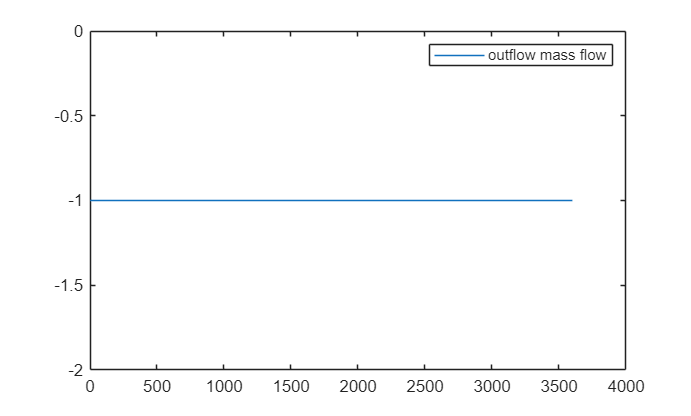

% Define the time vector and initial conditions for simulation
t = 1:1:3600;
x0 = ones(1, base_model.n) * 273.15 + 30; % Initial temperature
u = [
    ones(length(t), 1)*1,... % Varying input
    [ones(length(t)/2,1)*273.15+30;ones(length(t)/2,1)*273.15+50],... % Constant temperature input
    ones(length(t), 1) * 2e5 % Zero input for the third variable
];
result = dmsim(base_model, x0, [],[],t, u);

figure();
plot(result.tsim, result.y(:,9),'DisplayName','outflow mass flow')
legend

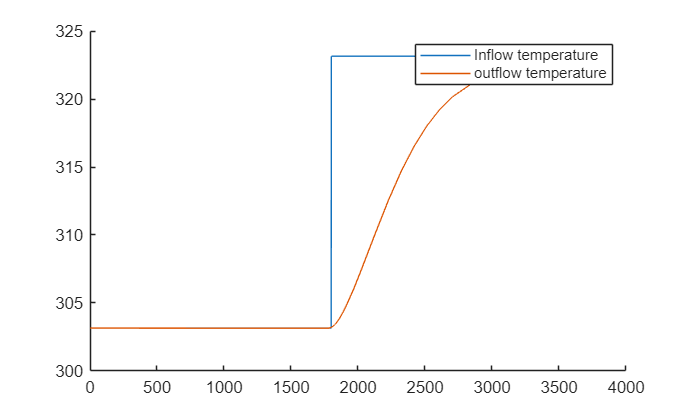


figure();
hold on 
plot(t, u(:,2),'DisplayName','Inflow temperature')
plot(result.tsim, result.y(:,10),'DisplayName','outflow temperature')
legend
hold off

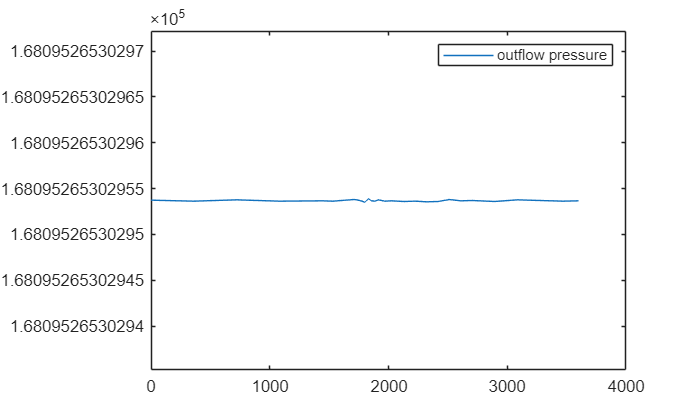


figure();
plot(result.tsim, result.y(:,11),'DisplayName','outflow pressure')
legend

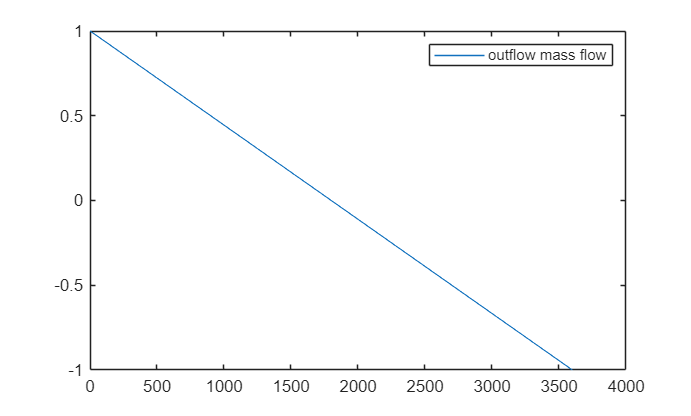

% Define the time vector and initial conditions for simulation
t = 1:1:3600;
x0 = ones(1, base_model.n) * 273.15 + 9; % Initial temperature
u = [
    linspace(-1, 1,length(t))',... % Varying input
    ones(length(t),1)*273.15+9,... % Constant temperature input
    ones(length(t), 1) * 2e5 % Zero input for the third variable
];
result = dmsim(base_model, x0, [],[],t, u);

figure();
plot(result.tsim, result.y(:,9),'DisplayName','outflow mass flow')
legend

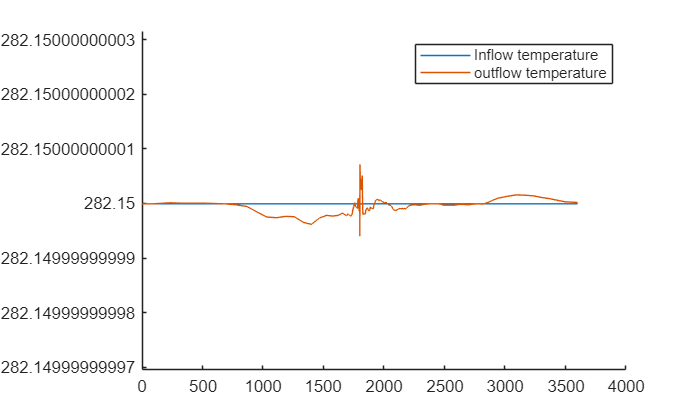


figure();
hold on 
plot(t, u(:,2),'DisplayName','Inflow temperature')
plot(result.tsim, result.y(:,10),'DisplayName','outflow temperature')
legend
hold off

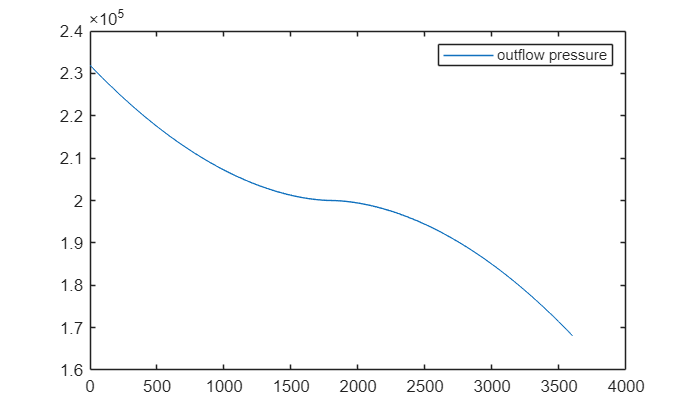


figure();
plot(result.tsim, result.y(:,11),'DisplayName','outflow pressure')
legend